# Práctica 1. Factorización QR

Ángel A. Gil Álamo (21067743L)

## 1. Método de Gram-Schmidt

Escriba, en el Apéndice A1, una función que implemente el método de Gram-Schmidt, que responda a la sintaxis

`    [Q,R] = QRGramSchmidt(A)`

### Probando el algoritmo

A continuación se presenta algunos casos de prueba, con explicaciones. Una vez implementado el código, los siguientes casos deberían poder ejecutarse 

Se prueba con la matriz $\mathbf{A}=\left\lbrack \begin{array}{cc}
1 & 1\\
-1 & 0
\end{array}\right\rbrack$.

A = [1,1;-1,0];
[Q,R]=QRGramSchmidt(A)

B =      1     1
    -1     0


Q =     0.7071    0.7071
   -0.7071    0.7071


R =     1.4142    0.7071
         0    0.7071


¿Es $\mathbf A = \mathbf Q \mathbf R$? Probar con la comparación ==

A == Q*R

ans = 2×2 logical array
   1   1
   1   1


Efectivamente coinciden.

Trabajar con números enteros es engañoso. Probar esta función con la matriz $\mathbf{A}=\left\lbrack \begin{array}{cc}
\pi  & 1\\
-1 & 0
\end{array}\right\rbrack$

¿Es $\mathbf A == \mathbf Q \mathbf R$?

A = [pi,1;-1,0];
[Q,R]=QRGramSchmidt(A)

B =     3.1416    1.0000
   -1.0000         0


Q =     0.9529    0.3033
   -0.3033    0.9529


R =     3.2969    0.9529
         0    0.3033


A == Q*R

ans = 2×2 logical array
   1   1
   0   1


No coinciden.

La comparación entre matrices y vectores se debe hacer siempre en norma

norm(A-Q*R)

ans = 1.1102e-16

Que efectivamente resulta casi $0$.

## 2. Método de Householder

2a. Escribir, en el Apéndice A2, una función implemente el método de Householder, que responda a la sintaxis

`    [Q,R] = QRHouseholder(A)`

Probando con la matriz $\mathbf A$ del ejercicio anterior

A = [1,1;-1,0];
[Q,R]=QRHouseholder(A);

B =     1.0000    1.0000
   -1.0000    0.0000


norm(A-Q*R)

ans = 9.4534e-16

## 3. Estudio de estabilidad

El siguiente se provee para comparar los métodos de Gram-Schmidt y Householder

La matriz del ejemplo de la comparación de estabilidad. Primero se construye unas matrices $\mathbf Q$ ortogonal y $\mathbf R$triangular superior, usando el algoritmo qr de MATLAB.

N = 80;
[U, ~] = qr(randn(N));
[V, ~] = qr(randn(N));
S = diag(2.^(-1:-1:-N));

[Q, R] = qr(U*S*V);

Se modifica la diagonal de $\mathbf R$, y se define $\mathbf A = \mathbf Q \mathbf R$

R(1:(N+1):N^2) = 2.^(-1:-1:-N);
A = Q*R;

Factorizamos con los algoritmos de Gram-Schmidt y Householder 

[QG, RG] = QRGramSchmidt(A);

B =    -0.0546   -0.0289   -0.0328    0.0035   -0.0007   -0.0032    0.0080   -0.0150    0.0009   -0.0019    0.0096   -0.0006    0.0067    0.0069    0.0112    0.0032    0.0058   -0.0053    0.0101    0.0036   -0.0056    0.0065    0.0043   -0.0057   -0.0041    0.0002   -0.0106    0.0047    0.0022   -0.0063   -0.0003    0.0097   -0.0047   -0.0006   -0.0006    0.0010    0.0018    0.0002    0.0158    0.0003   -0.0021    0.0127    0.0022    0.0102   -0.0061   -0.0003   -0.0026    0.0040   -0.0074   -0.0077
    0.0417    0.0019    0.0016    0.0023    0.0024    0.0005   -0.0055    0.0098   -0.0019    0.0004   -0.0076   -0.0018   -0.0018   -0.0035   -0.0076   -0.0001   -0.0053    0.0032   -0.0059   -0.0044    0.0033   -0.0050   -0.0001    0.0049    0.0012    0.0001    0.0066   -0.0028    0.0002    0.0041    0.0002   -0.0080    0.0025    0.0007    0.0013    0.0003   -0.0023   -0.0002   -0.0125   -0.0004    0.0011   -0.0061   -0.0019   -0.0074    0.0043   -0.0000    0.0021   -0.0022    0.0065    0

[QH, RH] = QRHouseholder(A);

B =    -0.0546   -0.0289   -0.0328    0.0035   -0.0007   -0.0032    0.0080   -0.0150    0.0009   -0.0019    0.0096   -0.0006    0.0067    0.0069    0.0112    0.0032    0.0058   -0.0053    0.0101    0.0036   -0.0056    0.0065    0.0043   -0.0057   -0.0041    0.0002   -0.0106    0.0047    0.0022   -0.0063   -0.0003    0.0097   -0.0047   -0.0006   -0.0006    0.0010    0.0018    0.0002    0.0158    0.0003   -0.0021    0.0127    0.0022    0.0102   -0.0061   -0.0003   -0.0026    0.0040   -0.0074   -0.0077
    0.0417    0.0019    0.0016    0.0023    0.0024    0.0005   -0.0055    0.0098   -0.0019    0.0004   -0.0076   -0.0018   -0.0018   -0.0035   -0.0076   -0.0001   -0.0053    0.0032   -0.0059   -0.0044    0.0033   -0.0050   -0.0001    0.0049    0.0012    0.0001    0.0066   -0.0028    0.0002    0.0041    0.0002   -0.0080    0.0025    0.0007    0.0013    0.0003   -0.0023   -0.0002   -0.0125   -0.0004    0.0011   -0.0061   -0.0019   -0.0074    0.0043   -0.0000    0.0021   -0.0022    0.0065    0

#### Estimación en norma

Calculamos la comparación adecuada es en norma matricial

norm(A-QG*RG)

ans = 6.7459e-17

norm(A-QH*RH)

ans = 2.5788e-16

Efectivamente, en norma parece que las matrices están bien descompuestas

#### Veamos qué ocurre con los elementos $r_{jj}$

Representamos los elementos diagonales en escala logarítmica

semilogy(diag(RG),'x');
hold on
semilogy(diag(RH),'o');
semilogy(abs(diag(R)),'--', 'Linewidth', 2);

Representamos el epsilon de máquina y su raíz

semilogy(sqrt(eps)*ones(N,1), 'Linewidth', 2);
semilogy(eps*ones(N,1), 'Linewidth', 2);
hold off
axis tight

Añadimos título y leyenda

h = legend('$r_{jj}$ Gram-Schmidt',...
           '$r_{jj}$ Householder',...
           '$r_{jj}$ ``exactos''''','$\sqrt{\epsilon}$', '$\epsilon$');
set(h, 'Interpreter', 'Latex', 'FontSize', 18, 'Location', 'SouthWest')

xlabel('$j$', 'Interpreter', 'Latex');

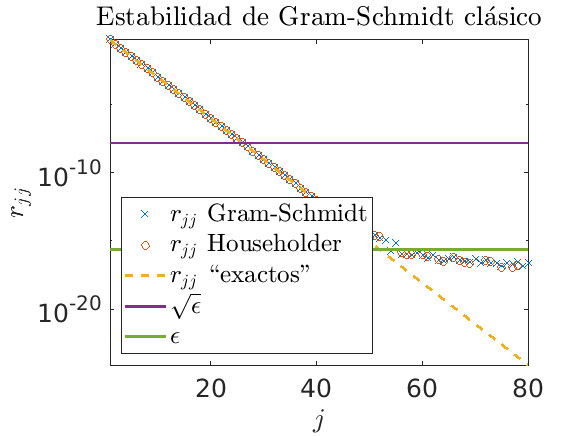

ylabel('$r_{jj}$', 'Interpreter', 'Latex');
title("Estabilidad de Gram-Schmidt cl\'asico", 'Interpreter', 'Latex')

set(gca, 'FontSize', 18)

# Apéndice A. Sección de funciones

A1. Algoritmo de Gram Schmidt clásico para factorización QR

function [Q,R] = QRGramSchmidt(A)
[m,n] = size(A);
R = zeros(n);
Q = zeros(m,n);
R(1,1) = norm(A(:,1));
Q(:,1) = A(:,1)/R(1,1);
for j = 2:n
    for i = 1:(j-1)
        R(i,j) = dot(Q(:,i),A(:,j));
        A(:,j) = A(:,j)- R(i,j)*Q(:,i);
    end
    R(j,j) = norm(A(:,j));
    Q(:,j) = A(:,j)/R(j,j);
end
B = Q*R
end

A2. Algoritmo de Householder para factorización QR

function [Q,R] = QRHouseholder(A)
[n,m] = size(A);
Q = eye(n,n);
R = A;
for i = 1:m-1
    x = (R(i:m,i))';
    vpos = norm(x)*eye(m-i+1,1)- x';
    vneg = -norm(x)*eye(m-i+1,1) - x';
    if norm(vpos) >= norm(vneg)
        v = vpos;
    else
        v = vneg;
    end
    F = eye(m-i+1, m-i+1) - 2*(v*v')/(norm(v)^2);
    Qtemp= eye(m,m);
    Qtemp(i:m,i:m) = F(1:m-i+1,1:m-i+1);
    R = Qtemp*R;
    Q = Q*(Qtemp)';
end
B= Q*R
end